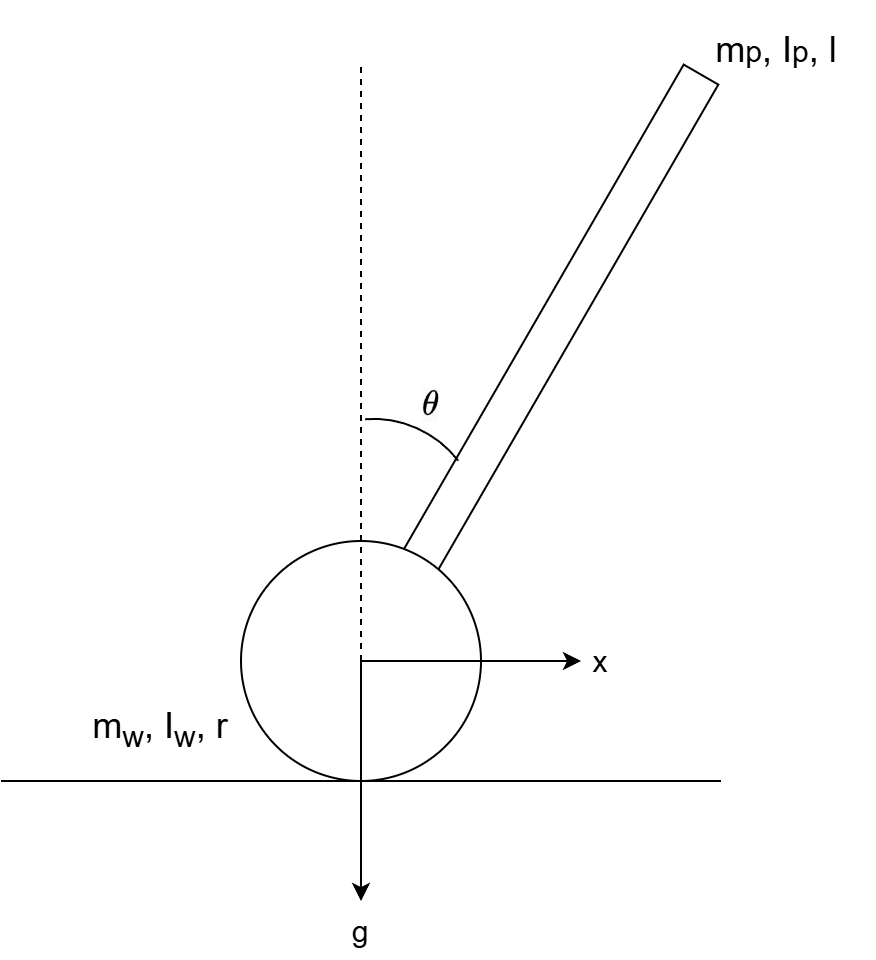


clc;
clear all;

syms mp mw Iw Ip r g t F l

syms x(t) theta(t)

xdot    = diff(x, t);
thetadot = diff(theta, t);

xddot    = diff(x, t, t);
thetaddot = diff(theta, t, t);

Kinetic Energy

T_wheels = 2 * (0.5*mw*xdot^2 + 0.5*Iw*(xdot/r)^2);

xp = x + l*sin(theta);
yp = l*cos(theta);

dxp = diff(xp,t);
dyp = diff(yp,t);

T_pend_trans = 0.5*mp*(dxp^2 + dyp^2);
T_pend_rot = 0.5*Ip*thetadot^2;

T = simplify(T_wheels + T_pend_trans + T_pend_rot)

$$T(t) = \begin{array}{l} \frac{\mathrm{mp}\,\left({\left(\frac{\partial }{\partial t}x\left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+l^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,\sigma_{2}\right)}{2}+\frac{\mathrm{Ip}\,\sigma_{2}}{2}+\mathrm{mw}\,\sigma_{1}+\frac{\mathrm{Iw}\,\sigma_{1}}{r^{2}}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

Potential Energy

V = - mp*g*l*cos(theta) 

$$V(t) = -g\,l\,\mathrm{mp}\,\cos\left(\theta \left(t\right)\right)$$

Lagrangian

L = simplify(T - V)

$$L(t) = \begin{array}{l} \frac{\mathrm{mp}\,\left({\left(\frac{\partial }{\partial t}x\left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+l^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,\sigma_{2}\right)}{2}+\frac{\mathrm{Ip}\,\sigma_{2}}{2}+\mathrm{mw}\,\sigma_{1}+\frac{\mathrm{Iw}\,\sigma_{1}}{r^{2}}+g\,l\,\mathrm{mp}\,\cos\left(\theta \left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

Euler–Lagrange Equations

dL_dxdot = diff(L, xdot);
EL_x = simplify(diff(dL_dxdot, t) - diff(L, x))

$$EL\_x(t) = \mathrm{mp}\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,\mathrm{mw}\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\frac{2\,\mathrm{Iw}\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)}{r^{2}}-l\,\mathrm{mp}\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+l\,\mathrm{mp}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)$$


dL_dthetadot = diff(L, thetadot);
EL_theta = simplify(diff(dL_dthetadot, t) - diff(L, theta))

$$EL\_theta(t) = \mathrm{mp}\,l^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\mathrm{mp}\,\cos\left(\theta \left(t\right)\right)\,l\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\mathrm{Ip}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+g\,\mathrm{mp}\,\sin\left(\theta \left(t\right)\right)\,l$$


EL_x_mod = EL_x - F;